**UVP light unit calibration** Version 2018/11/23

clear all; close all

## DATE analyse

disp(datestr(now,31))

2021-03-17 15:48:19


## PEOPLE analyse

people = input('Enter people first and last name (Marc Picheral) ','s');
if isempty(people); people = 'Marc Picheral'; end
disp(['Processing operator : ' char(people)]);

Processing operator : Marc Picheral


## IMAGE DATA

disp('Select folder (snXXX\eclairage_caracterisation\YYYYMMDD_HHMM_ver01_ver02) ')

Select folder (snXXX\eclairage_caracterisation\YYYYMMDD_HHMM_ver01_ver02) 


disp('containing the 2 light image folders and the background_image.tiff file ' );

containing the 2 light image folders and the background_image.tiff file 


drive_root = uigetdir('Select directory');

## Image acquisition date, UVP serial number & light numbers

aa = findstr(drive_root,'\');
date_vue = drive_root(aa(end)+1:end);year = date_vue(1:4);month = date_vue(5:6);
day = date_vue(7:8);
list_dir = dir(drive_root);uvp5sn = drive_root(aa(end-2)+1 : aa(end-1)-1);
ata = find([list_dir(1:end).isdir] == 1);
index_ver1 = ata(end-1); index_ver2 = ata(end);

## Settings

[pxs,px,orient,longmm,large,longpx,uvp,a,b,c,d,level,cor_img,img_ref_size] = somme_eclairage_settings(uvp5sn);

## Matrice de correction vignetage

corr_matrix = get_correction_matrix(drive_root);

--------- Reading correction matrix ------------


## Process first light

verrine01 = list_dir(index_ver1).name;disp(['Light : ',char(verrine01)])

Light : verdp007r


[base1,Centre1]= Calculs_eclairages_uvp5_tr_param([list_dir(index_ver1).folder...
    ,'\',list_dir(index_ver1).name,'\'],a,b,c,d,level,cor_img,img_ref_size,corr_matrix);

Rep = Z:\UVP5\Instruments\sn200\eclairage_caracterisation\20210317_1200_verdp007r_verdp008l\verdp007r\
Image : 1
Image : 2
Image : 3
Image : 4
Image : 5
Image : 6
Image : 7
Image : 8
Image : 9


## Process second light

verrine02 = list_dir(index_ver2).name;disp(['Light : ',char(verrine02)])

Light : verdp008l


[base2,Centre2] = Calculs_eclairages_uvp5_tr_param([list_dir(index_ver2).folder...
    ,'\',list_dir(index_ver2).name,'\'],a,b,c,d,level,cor_img,img_ref_size,corr_matrix);

Rep = Z:\UVP5\Instruments\sn200\eclairage_caracterisation\20210317_1200_verdp007r_verdp008l\verdp008l\
Image : 1
Image : 2
Image : 3
Image : 4
Image : 5
Image : 6
Image : 7
Image : 8
Image : 9


## Separated lights and resulting data files proces

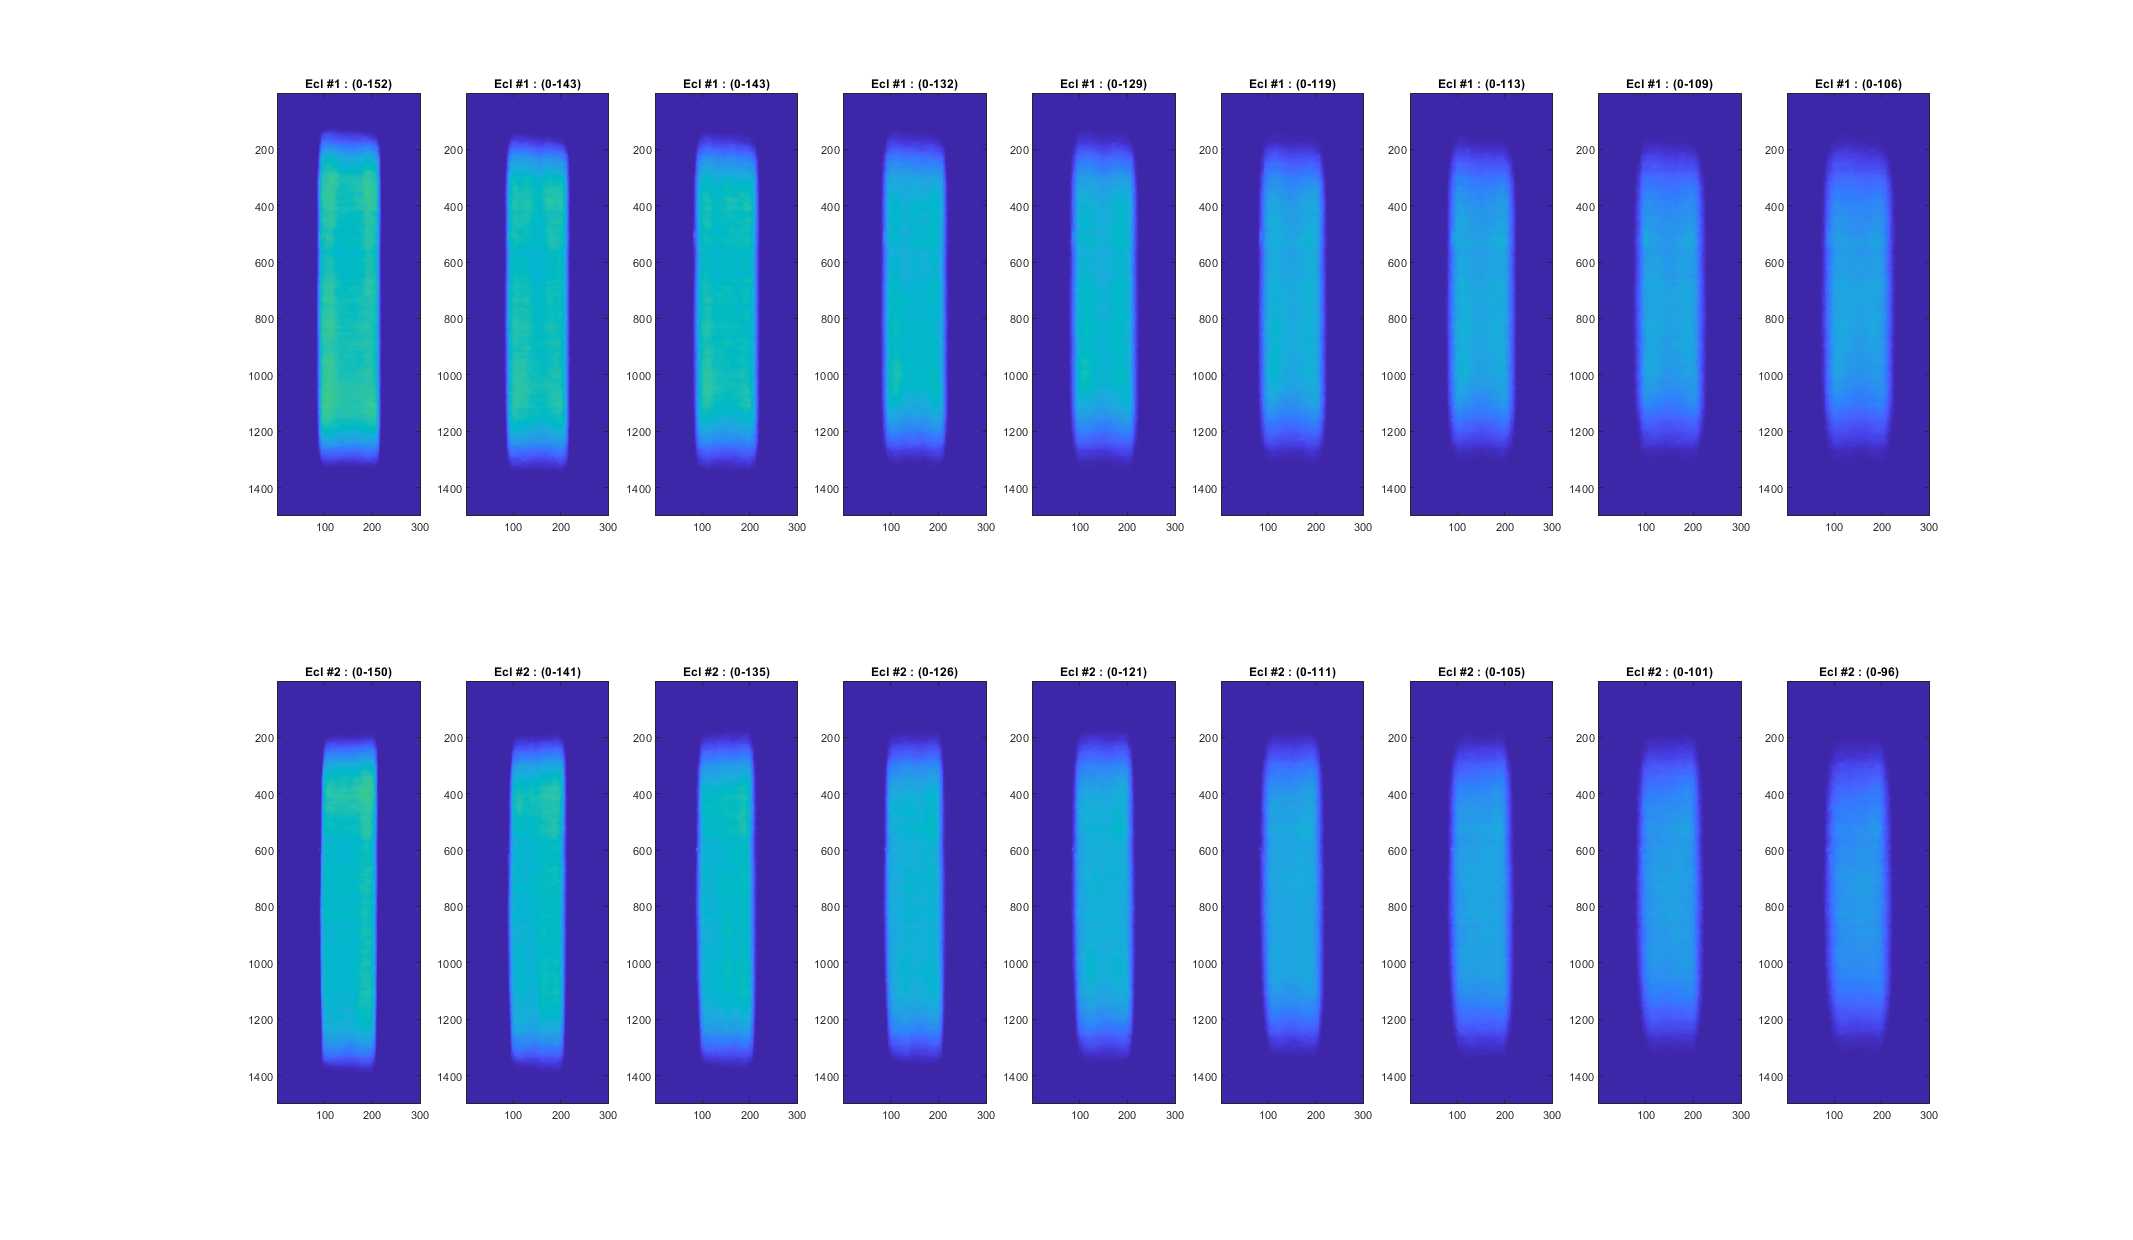

Figure_2_lights(base1,base2,date_vue,drive_root,uvp5sn,verrine01,verrine02)

## Process total volume

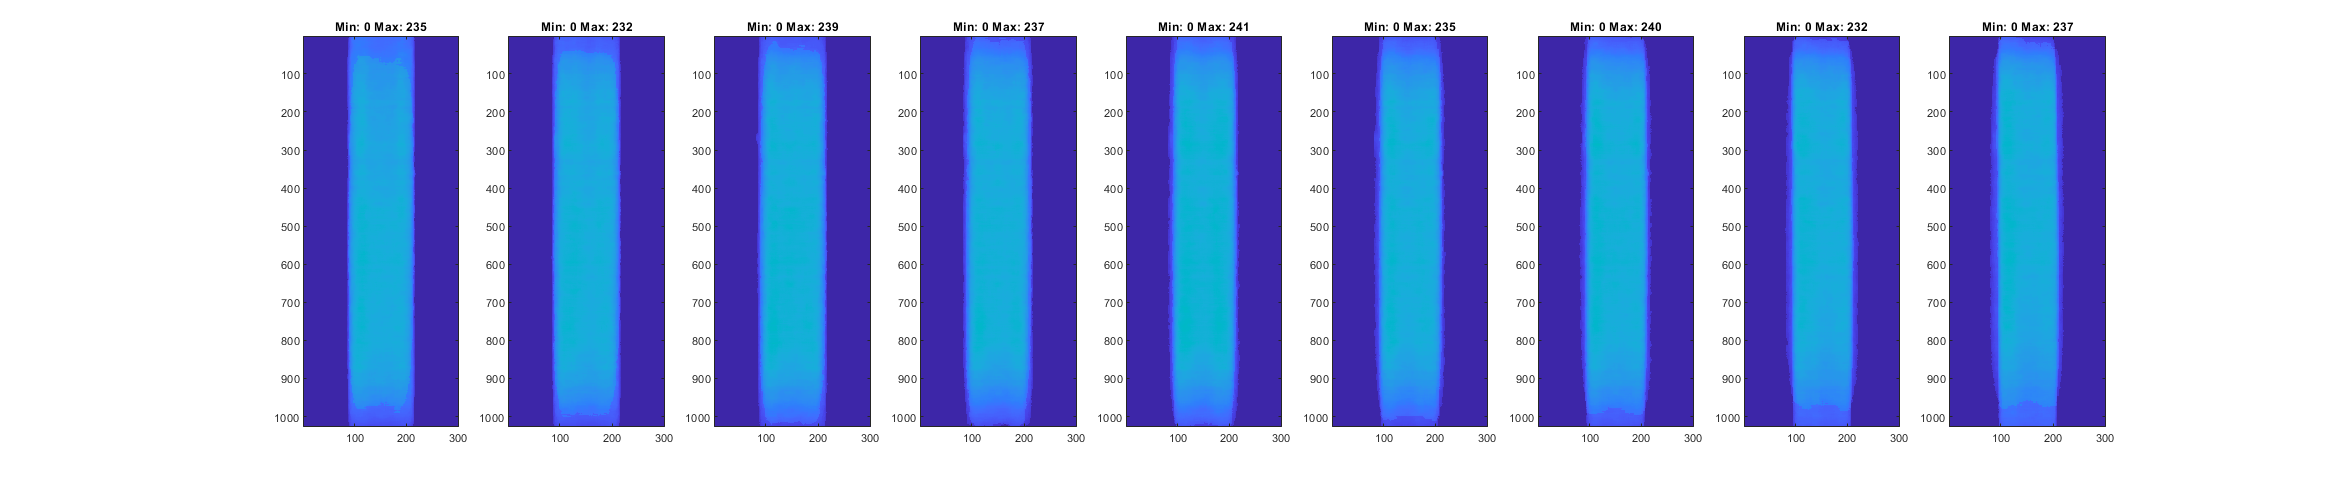

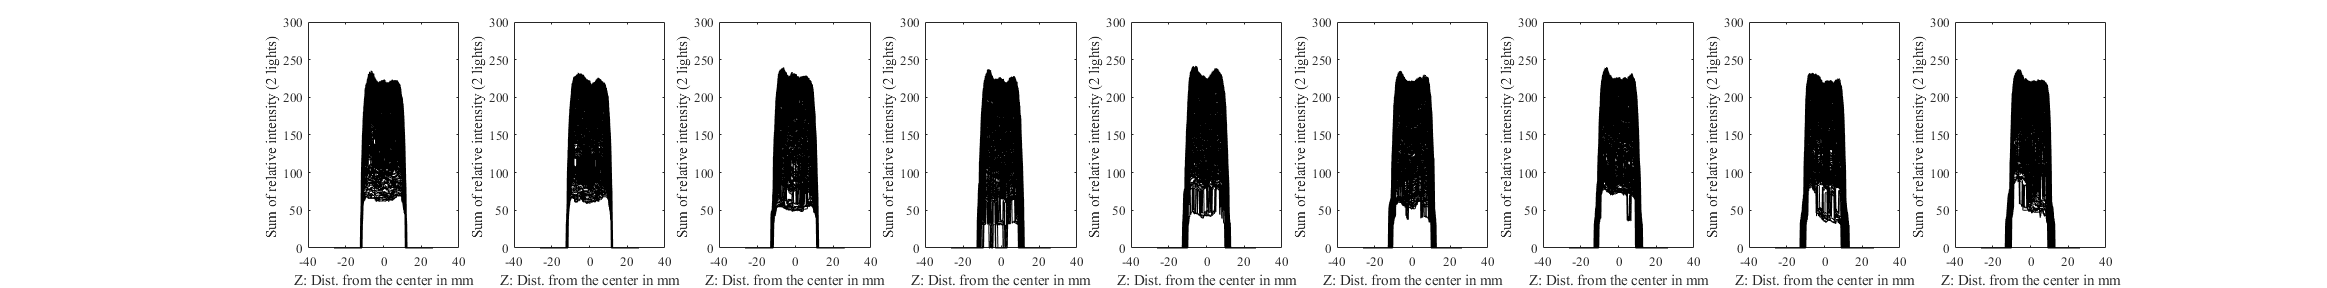

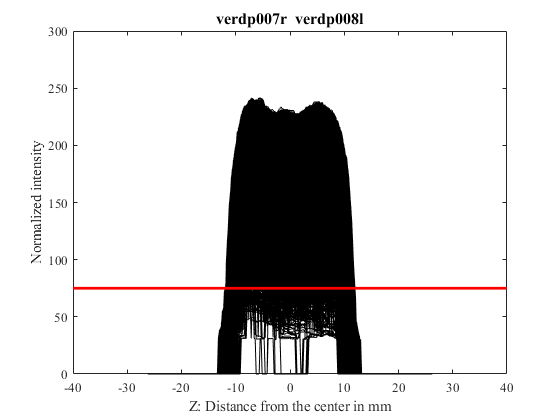

[b max_int vol vol_100 cor_int seuil_vol_fixe] = Somme_eclairage_new_corr...
    (uvp5sn,drive_root,base1,base2,longpx,large,px,longmm,verrine01,verrine02...
    ,a,b,c,d,img_ref_size,cor_img,Centre1,Centre2);

## Resulting data

Somme_images_results(drive_root,uvp5sn,date_vue,verrine01,verrine02,large,longmm,...
    b,max_int,vol,vol_100,cor_int,level,cor_img,base1,base2,seuil_vol_fixe)

UVP=       UVP5sn200
Date_img=           20210317_1200_verdp007r_verdp008l
light_1=            verdp007r
light_1 (I_mean) =  81.6404
light_1 (I_min) =   60.3607
light_1 (I_max) =   105.6544
light_2=            verdp008l
light_2 (I_mean) =  76.7024
light_2 (I_min) =   51.6865
light_2 (I_max) =   99.3213
Mean uncorrected Intensity (light1 + Light2) =  193
X=                  188
Y=                  188
Volume_s75=        0.80378
Z=                  22.7417
I_mean (mean int of all img) =            236
I_min (min int of all img) =              232
I_max (max int of all img) =              241
I_cor=              1
Img_range=          16
Img_step=           2
